clear

%Default values if not entered in GUI popup
absorbanceSelected = 0;
emissionSelected = 0;
excitationSelected = 0;
normaliseSelected = 0;
redEdgeSelected = 0;

resultVariables = GUIScript(); %Get values from GUI popup

%If press cancel, stop code
if isempty(resultVariables)
    disp('Canceled');
    return;
end

%Save variables from GUI popup
absorbanceSelected = resultVariables.absorptionYN;
emissionSelected = resultVariables.emissionYN;
excitationSelected = resultVariables.excitationYN;
normaliseSelected = resultVariables.normaliseYN;
redEdgeSelected = resultVariables.rededgeYN;
Sample = cell2mat(resultVariables.SampleName);
Solvent = cell2mat(resultVariables.SolventName);
ConcentrationAmount = cell2mat(resultVariables.ConcentrationNum);
ConcentrationUnits = resultVariables.SelectedUnit;

ConcentrationOptions = {'M', 'mM', 'uM', 'nM'};
ConcentrationValues = {1, 1E-3, 1E-6, 1E-9};
if any(strcmp(ConcentrationUnits, ConcentrationOptions))
    concentrationPosition = find(strcmp(ConcentrationUnits, ConcentrationOptions));
    concentration = ConcentrationValues{concentrationPosition};
else
    disp('No concentration set.');
    concentration = 1
end

%smooth data increment if set to yes (tied to spectrometer spectral resolution)
if resultVariables.smoothYN == 1
   smoothStepsize = 7;
else
   smoothStepsize = 1;
end

Solventname = [ConcentrationAmount + " " + ConcentrationUnits + " " + Sample + " in " + strrep(Solvent,  '_', ' ')];

%Initial concentration (note does not factor in chromophores for tethered molecules, can x2 here if tethered molecules)
initialConcentration = concentration*str2double(ConcentrationAmount)*2;

%folder processing, finding data based on file heirachy (save under: Samplename/SamplenameSolventConcentration/ with csv filename suffix below)
curfolder = pwd;
folderPath = fullfile([curfolder, '\', Sample, '\', Sample, Solvent, ConcentrationAmount, ConcentrationUnits]);
fileNameExtinction = fullfile([Sample, Solvent, ConcentrationAmount, ConcentrationUnits, 'AbsorbanceMatlab.csv']);
fileNameEmission = fullfile([Sample, Solvent, ConcentrationAmount, ConcentrationUnits, 'EmissionMatlab.csv']);
fileNameExcitation = fullfile([Sample, Solvent, ConcentrationAmount, ConcentrationUnits, 'ExcitationMatlab.csv']);

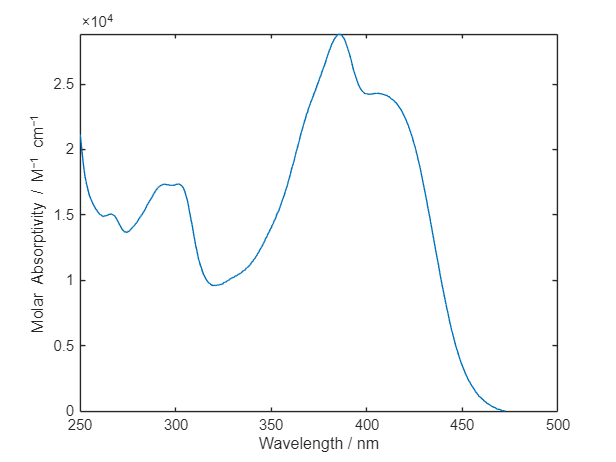

%Extinction Spectrum
if exist(fullfile(folderPath, fileNameExtinction), 'file') && absorbanceSelected == 1
    fileDataExtinction = importdata(fullfile(folderPath, fileNameExtinction));
    extinctionWavelength = fileDataExtinction.data(1:end,3);
    intensityDataExtinction = fileDataExtinction.data(1:end,4);
    intensityDataMolarAbs = intensityDataExtinction/initialConcentration;
    extinctionWave = extinctionWavelength;
    extinctionIntensity = intensityDataMolarAbs;
    maxExtinctionIntensity = max(intensityDataExtinction);
    normalizedExtinctionIntensity = extinctionIntensity/maxExtinctionIntensity;

    figure;
    plot(extinctionWave, intensityDataMolarAbs, "LineStyle","-","Marker","none");
    xlabel('Wavelength / nm');
    ylabel('Molar Absorptivity / M^{−1} cm^{−1}');
    xlim([250 500]) %change for preference
    ylim([-1 inf]) 
end

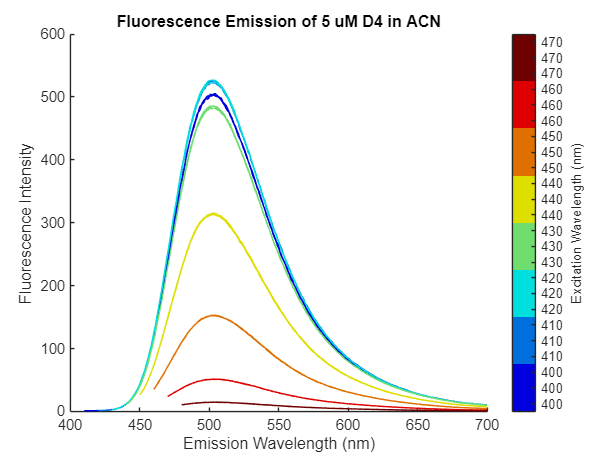

%Fluorescence Emission Spectra, csv processed is unique to our spectrometer output
if exist(fullfile(folderPath, fileNameEmission), 'file') && emissionSelected == 1
    fileDataEmission = importdata(fullfile(folderPath, fileNameEmission));
    [rowsEmissionFluoro, colsEmissionFluoro] = size(fileDataEmission.data);
    excitationWavelengthsUnsortedEmissionFluoro = cell(1, colsEmissionFluoro/ 2);    
    wavelengthsUnsortedEmissionFluoro = cell(1,colsEmissionFluoro/2);
    intensityDataUnsortedEmissionEmissionFluoro = cell(1,colsEmissionFluoro/2);
    intensityDataSmoothedUnsortedEmissionFluoro = cell(1,colsEmissionFluoro/2);
    
            for i = 2:2:(colsEmissionFluoro)
                    wavelengthsUnsortedEmissionFluoro{i/2} = fileDataEmission.data(1:end,(i-1));
                    cellContentEmission = fileDataEmission.textdata{1, 1};
                    matchEmission = regexp(cellContentEmission, '(\d+)nm', 'tokens');
                    matchRepeat = regexp(cellContentEmission, '(\d+)nm([A-Z])', 'match');
                    excitationWavelengthsUnsortedEmissionFluoro{i/2} = str2double(matchEmission{i/2}); %grab wavelength and ID
                    intensityDataUnsortedEmissionEmissionFluoro{i/2} = fileDataEmission.data(:, i); %grab fluorescence emission intensity
                    intensityDataSmoothedUnsortedEmissionFluoro{i/2} = movmean(intensityDataUnsortedEmissionEmissionFluoro{i/2}, smoothStepsize); %smooth
            end 
    
    fluoroExcitationNumeric = cell2mat(excitationWavelengthsUnsortedEmissionFluoro);
    samplesUnique = unique(fluoroExcitationNumeric); %Find unique samples (A, B, C etc)
    repeatSamples = width(fluoroExcitationNumeric)/length(samplesUnique);
    customColormapEmissionFluoro = jet(length(samplesUnique))/1.15; %make colourmap for data

    [~, sortEmission] = sort(fluoroExcitationNumeric); %sort data by ascending wavelength
    
    excitationWavelengthsSortedEmissionFluoro = cell2mat(excitationWavelengthsUnsortedEmissionFluoro(sortEmission));
    fluoroExcitationNumericMatrix = reshape(excitationWavelengthsSortedEmissionFluoro, [repeatSamples, length(samplesUnique)]);
    %sort wavelengths
    wavelengthsSortedEmissionFluoro = wavelengthsUnsortedEmissionFluoro(sortEmission);
    wavelengthsSortedEmissionFluoroMatrix = reshape(wavelengthsSortedEmissionFluoro, [repeatSamples, length(samplesUnique)]);
    %sort fluorescence emission for data
    intensityDataSortedEmissionFluoro = intensityDataUnsortedEmissionEmissionFluoro(sortEmission);
    %sort fluorescence emission for smoothed data    
    intensityDataSmoothedSortedEmissionFluoro = intensityDataSmoothedUnsortedEmissionFluoro(sortEmission);
    intensityDataSmoothedSortedEmissionFluoroMatrix = reshape(intensityDataSmoothedSortedEmissionFluoro, [repeatSamples, length(samplesUnique)]);
    
    intensityDataUnsortedEmissionEmissionFluoroRS = reshape(intensityDataUnsortedEmissionEmissionFluoro, [length(samplesUnique), repeatSamples]);

%run code here if normalise selected, normalise and plot emission   
    if normaliseSelected == 1
        figure;
        hold on;
        for i = 1:repeatSamples
            for k = 1:length(samplesUnique)
                    maxIntensityEmission = max(intensityDataSmoothedSortedEmissionFluoroMatrix{i,k});
                    normalizedIntensityEmission = intensityDataSmoothedSortedEmissionFluoroMatrix{i,k}/maxIntensityEmission;
                    [maxEmission, idx] = max(normalizedIntensityEmission);
                    maxWave(k) = wavelengthsSortedEmissionFluoroMatrix{i,k}(idx);
                    plot(wavelengthsSortedEmissionFluoroMatrix{i,k}, normalizedIntensityEmission, 'color', customColormapEmissionFluoro(k, :));
            end
        end
        hold off;
        xlabel('Emission Wavelength / nm');
        ylabel('Normalised Fluorescence Intensity');
        %title("Normalised Fluorescence Emission of " + Solventname);
        %title(Solventname);
        c = colorbar('Location', 'eastoutside');
        colormap(c, customColormapEmissionFluoro);
        c.Label.String = 'Excitation Wavelength / nm';
        c.Ticks = linspace(0+(1/length(samplesUnique)/2), 1-(1/length(samplesUnique)/2), length(samplesUnique));
        c.TickLabels = arrayfun(@(x) sprintf('%02d', x), samplesUnique, 'UniformOutput', false);
        
        xlim('auto')
        ylim('auto')
        
    else %if normalise not selected
        figure;
        hold on;
        for i = 1:repeatSamples
            for k = 1:length(samplesUnique)
                plot(wavelengthsSortedEmissionFluoroMatrix{i,k}, intensityDataSmoothedSortedEmissionFluoroMatrix{i,k}, 'color', customColormapEmissionFluoro(k, :));
            end
        end
        hold off;
        xlabel('Emission Wavelength (nm)');
        ylabel('Fluorescence Intensity');
        title("Fluorescence Emission of " + Solventname);
        
        c = colorbar('Location', 'eastoutside');
        colormap(c, customColormapEmissionFluoro);
        c.Label.String = 'Excitation Wavelength (nm)';
        c.Ticks = linspace(0+(1/length(intensityDataSortedEmissionFluoro)/2), 1-(1/length(intensityDataSortedEmissionFluoro)/2), length(intensityDataSmoothedSortedEmissionFluoro));
        c.TickLabels = arrayfun(@(x) sprintf('%02d', x), excitationWavelengthsSortedEmissionFluoro, 'UniformOutput', false);
        
        xlim('auto')
        ylim('auto')
   end    
end

%Code for finding and plotting max emission wavelength as function of excitation wavelength
if exist(fullfile(folderPath, fileNameEmission), 'file') && exist(fullfile(folderPath, fileNameExtinction), 'file') &&  emissionSelected == 1 && absorbanceSelected == 1 && redEdgeSelected ==1
    for n = 1:repeatSamples   
        for m = 1:length(samplesUnique)
            if ~isempty(intensityDataSmoothedSortedEmissionFluoroMatrix{n,m})
            intensity = intensityDataSmoothedSortedEmissionFluoroMatrix{n,m};
            wavelength = wavelengthsSortedEmissionFluoroMatrix{n,m};
            wavelengthIndex = find(wavelengthsSortedEmissionFluoroMatrix{n,m} >= maxWave(m)-10 & wavelengthsSortedEmissionFluoroMatrix{n,m} <= maxWave(m)+10); %find data +/- 10 nm to max intensity
            xData = wavelength(wavelengthIndex);
            yData = intensity(wavelengthIndex);
                gaussianFit = fit(xData, yData, 'gauss1'); %fit a Gaussian to peak found in range
            middleOfPeak = gaussianFit.b1;
            FitMaximum(m,n) = middleOfPeak;
            end
        end
    end

    FitMaximumAvg = mean(FitMaximum,2);
    FitMaximumUpperError = max(FitMaximum,[],2) - FitMaximumAvg;
    FitMaximumLowerError = FitMaximumAvg - min(FitMaximum,[],2);

    
%plot data for red-edge effect
figure;
hold on
yyaxis right;
% hOriginal = plot(samplesUnique, transpose(FitMaximumAvg), 'Marker', 'square');
errorbar(samplesUnique, FitMaximumAvg, FitMaximumLowerError, FitMaximumUpperError, "o", MarkerFaceColor="auto");
ylabel('Fluorescence Maximum Wavelength / nm')
ylim([502.5 505])
%ylim([480 485])
yyaxis left;
plot(extinctionWave, extinctionIntensity)
xlim([380 480])
%ylim([0 3E4])
ylim([0 2.5E4])
xlabel('Wavelength / nm');
ylabel('Molar Absorptivity / M^{−1} cm^{−1}')
% title("Absorbance and Fluorescence Shift of " + Solventname);
hold off


end

%GUI code
function variables = GUIScript()

    fig = uifigure('Name', 'Please fill out the entries below', 'Position', [100, 100, 400, 250]);

    options = {'Absorbance', 'Emission', 'Excitation'};
    concentrationOptions = {'M', 'mM', 'uM', 'nM'};
    numOptions = numel(options);
    variables = struct();

    checkBoxLabel = uilabel(fig, 'Text', 'Show:', 'Position', [260, 225, 150, 22]);
    checkboxWidth = 100;
    checkboxHeight = 22;
    checkboxes = gobjects(1, numOptions);
    for i = 1:numOptions
        checkboxes(i) = uicheckbox(fig, 'Text', options{i}, 'Position', [260, 225 - 25 * i, checkboxWidth, checkboxHeight]);
    end
    
    checkBox2Label = uilabel(fig, 'Text', 'Options:', 'Position', [260, 100, 100, 22]);
    checkboxes(4) = uicheckbox(fig, 'Text', 'Normalise Data', 'Position', [260, 100 - 25, checkboxWidth, checkboxHeight]);
    checkboxes(5) = uicheckbox(fig, 'Text', 'Smooth Data', 'Position', [260,  100 - 50, checkboxWidth, checkboxHeight]);
    checkboxes(6) = uicheckbox(fig, 'Text', 'Red Edge Check', 'Position', [260,  100 - 75, checkboxWidth+10, checkboxHeight]);
    
    textbox1Label = uilabel(fig, 'Text', 'Sample name:', 'Position', [50, 200, 150, 22]);
    textbox1 = uitextarea(fig, 'Position', [50, 180, 150, 22]);

    textbox2Label = uilabel(fig, 'Text', 'Solvent used:', 'Position', [50, 150, 150, 22]);
    textbox2 = uitextarea(fig, 'Position', [50, 130, 150, 22]);

    textbox3Label = uilabel(fig, 'Text', 'Concentration:', 'Position', [50, 100, 80, 22]);
    textbox3 = uitextarea(fig, 'Position', [50, 80, 80, 22]);
    
    % Create dropdown list
    dropdownLabel = uilabel(fig, 'Text', '', 'Position', [130, 100, 70, 22]);
    dropdown = uidropdown(fig, 'Items', concentrationOptions, 'Position', [130, 80, 70, 22]);
    
    confirmButton = uibutton(fig, 'Text', 'Confirm', 'Position', [50, 20, 70, 30], 'ButtonPushedFcn', @(btn, event) confirmSelection());
    cancelButton = uibutton(fig, 'Text', 'Cancel', 'Position', [130, 20, 70, 30], 'ButtonPushedFcn', @(btn, event) cancelSelection());
    
    loadState();
    
    function confirmSelection()
        variables.absorptionYN = checkboxes(1).Value;
        variables.emissionYN = checkboxes(2).Value;
        variables.excitationYN = checkboxes(3).Value;
        variables.normaliseYN = checkboxes(4).Value;
        variables.smoothYN = checkboxes(5).Value;
        variables.rededgeYN = checkboxes(6).Value;
        
        variables.SampleName = textbox1.Value;
        variables.SolventName = textbox2.Value;
        variables.ConcentrationNum = textbox3.Value;
        
        variables.SelectedUnit = dropdown.Value;
        
        save('guiState.mat', 'variables');
        
        disp(variables);
        close(fig);
    end

    function cancelSelection()
        disp('Aborted');
        close(fig);
        return;
    end
    
    function loadState()
        % Load previous values from the MATLAB file
        if exist('guiState.mat', 'file')
            load('guiState.mat', 'variables');
            
            % Set the values in the UI components
            checkboxes(1).Value = variables.absorptionYN;
            checkboxes(2).Value = variables.emissionYN;
            checkboxes(3).Value = variables.excitationYN;
            checkboxes(4).Value = variables.normaliseYN;
            checkboxes(5).Value = variables.smoothYN;

            textbox1.Value = variables.SampleName;
            textbox2.Value = variables.SolventName;
            textbox3.Value = variables.ConcentrationNum;

            dropdown.Value = variables.SelectedUnit;
        end
    end
    
    movegui(fig, 'center');
    uiwait(fig);

end
